clear;      % Removes all variables from the workspace
clc;        % Clears the Command Window
close all;  % Closes any hidden or external figure windows

raw_data = load("identification_data\rod_2_identification\matlab.mat");

% Unpack the loaded data into struct
angles = 15:15:120;

for i = 1:length(angles)
    var_name = sprintf('theta_2_%d_degrees', angles(i));
    data = raw_data.(var_name);

    expData(i).t = data.Time;
    expData(i).y_raw = data.Data;
    expData(i).u = zeros(size(data.Time));
    expData(i).initial_angle = angles(i);
end

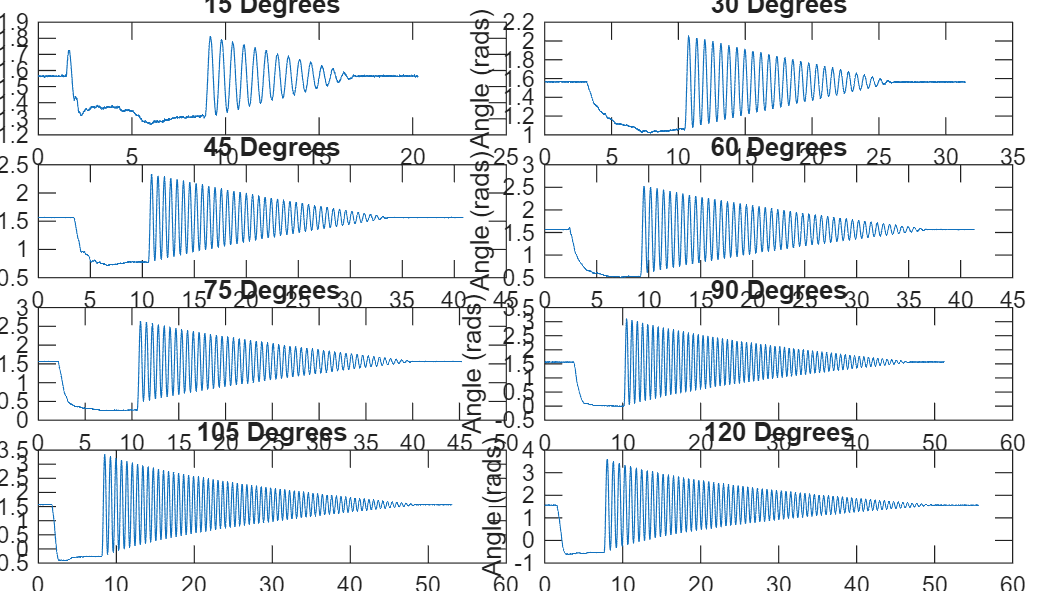

% Plotting raw data in time domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(angles)
    nexttile;
    plot(expData(i).t, expData(i).y_raw, "DisplayName", "Raw Data");
    title(sprintf('%d Degrees', angles(i)));
    ylabel("Angle (rads)");
    xlabel("Time (s)");
end

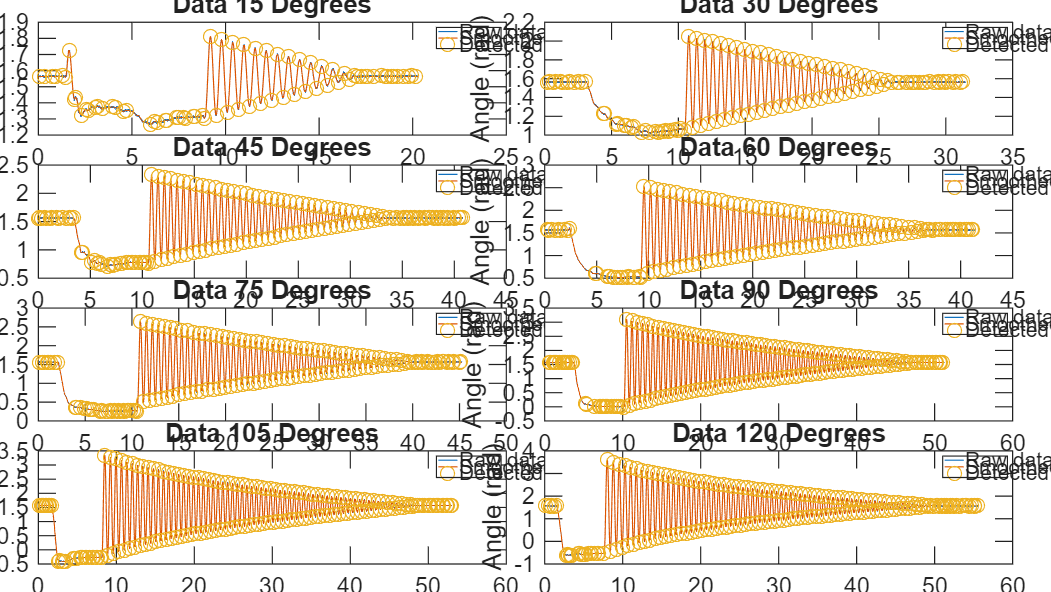

% Plot data with peak detection to truncate usefull data
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    % Filter out noise for peak detection
    fc = 5;     % Cut off frequency
    [b, a] = butter(3, fc/(fs/2), 'low');
    
    expData(i).y_smooth = filtfilt(b, a, expData(i).y_raw);

    % Find peaks
    minDist = round(0.3 * fs);
    [pMax, locMax] = findpeaks(expData(i).y_smooth, 'MinPeakDistance', minDist);
    [pMin, locMin] = findpeaks(-expData(i).y_smooth, 'MinPeakDistance', minDist);
    peak_indices = sort([locMax; locMin]);
    
    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t, expData(i).y_raw, 'DisplayName', 'Raw data');
    hold on;
    plot(expData(i).t, expData(i).y_smooth, 'DisplayName', 'Smoothed Data');
    plot(expData(i).t(peak_indices), expData(i).y_smooth(peak_indices), 'o', 'DisplayName', 'Detected peaks');
    
    legend;
    title(sprintf('Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

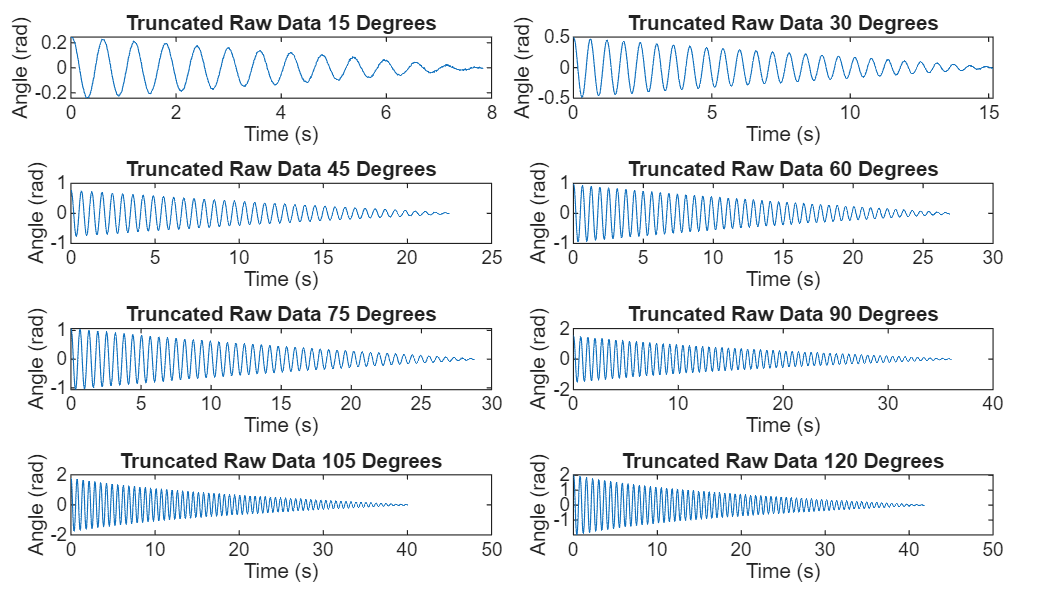

% Set indices for truncated data
expData(1).start_index = 919;
expData(1).end_index = 1703;

expData(2).start_index = 1078;
expData(2).end_index = 2594;

expData(3).start_index = 1089;
expData(3).end_index = 3339;

expData(4).start_index = 955;
expData(4).end_index = 3643;

expData(5).start_index = 1091;
expData(5).end_index = 3969;

expData(6).start_index = 1051;
expData(6).end_index = 4656;

expData(7).start_index = 851;
expData(7).end_index = 4857;

expData(8).start_index = 802;
expData(8).end_index = 4984;

for i = 1:length(angles)
    expData(i).y_id = expData(i).y_raw(expData(i).start_index:expData(i).end_index);
    expData(i).y_id = expData(i).y_id - mean(expData(i).y_raw(expData(i).end_index + 1:end));
    expData(i).t_id = expData(i).t(expData(i).start_index:expData(i).end_index);
    expData(i).t_id = expData(i).t_id - expData(i).t_id(1);
    expData(i).u_id = zeros(length(expData(i).y_id), 1);
end

% Plot truncated data time and frequency domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t_id, expData(i).y_id);

    title(sprintf('Truncated Raw Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Calc sampling period and frequency
    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    data_length = length(expData(i).y_id);

    % Compute the FFT
    y_fft = fft(expData(i).y_id);
    
    % Compute the two-sided spectrum P2
    P2 = abs(y_fft / data_length);
    
    % Compute the single-sided spectrum P1 based on P2
    P1 = P2(1:floor(data_length/2)+1);
    
    % Multiply by 2 to conserve energy (excluding DC and Nyquist frequencies)
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Define the frequency domain f (up to the Nyquist frequency)
    f = fs * (0:floor(data_length/2)) / data_length;
    
    nexttile;
    plot(f, P1, 'LineWidth', 1.2);
    
    title(sprintf('Raw Data %d Degrees', angles(i)));
    xlabel("Frequency (Hz)");
    ylabel("Amplitude");
    xscale('log')
end

%% ================================================================
% Identification setup - passive rod 2
%
% This section assumes that the preprocessing above has already created:
%   expData(i).y_id
%   expData(i).t_id
%   expData(i).u_id
%
% Required model files:
%   passive_rod_viscous_model.m
%   passive_rod_coulomb_model.m
%   passive_rod_lowvel_model.m
%
% Staged identification:
%   1) Viscous + gravity model
%   2) Coulomb-viscous model
%   3) Low-velocity damping model warm start
%   4) Full multistart low-velocity damping model
% ================================================================

%% Estimation and validation experiments
idxEst = [1 3 5 7];  % 15, 45, 75, 105 degrees
idxVal = [2 4 6 8];  % 30, 60, 90, 120 degrees

%% Create iddata objects
Ts = expData(1).t_id(2) - expData(1).t_id(1);

z = cell(length(angles), 1);

for i = 1:length(angles)

    y = expData(i).y_id(:);
    u = expData(i).u_id(:);

    y = double(y);
    u = double(u);

    if length(y) ~= length(u)
        error("Experiment %d: y_id and u_id do not have the same length.", i);
    end

    z{i} = iddata(y, u, Ts);

    z{i}.Name = sprintf('%d_deg', angles(i));
    z{i}.InputName = {'u'};
    z{i}.OutputName = {'theta'};
    z{i}.InputUnit = {'-'};
    z{i}.OutputUnit = {'rad'};
    z{i}.TimeUnit = 's';
end

zEst = mergeIddataExperiments(z, idxEst);
zVal = mergeIddataExperiments(z, idxVal);

%% Estimate rough initial guesses from the data
[pb2_init, pg2_init] = estimateInitialPassiveGuess(expData, idxEst);

fprintf("\nInitial rough guesses from data:\n");


Initial rough guesses from data:


fprintf("p_b2 = %.6f\n", pb2_init);

p_b2 = 0.174862


fprintf("p_g2 = %.6f\n\n", pg2_init);

p_g2 = 105.936894




%% General estimation options
opt = nlgreyestOptions;
opt.Display = 'on';
opt.SearchOptions.MaxIterations = 80;

%% ================================================================
% Stage 1: viscous + gravity model
%
% theta_ddot = -p_b2 theta_dot - p_g2 sin(theta)
% ================================================================

fprintf("\n============================================================\n");

fprintf("Stage 1: Viscous + gravity model\n");

Stage 1: Viscous + gravity model


fprintf("============================================================\n");


pVisc0.p_b2 = pb2_init;
pVisc0.p_g2 = pg2_init;

mVisc0 = createPassiveViscousModel(expData, idxEst, pVisc0);

mVisc = nlgreyest(zEst, mVisc0, opt);
mVisc.Name = 'Viscous';

dispPassiveParameters(mVisc);

mVisc_val = setPassiveInitialStates(mVisc, expData, idxVal);

[~, fitViscEst] = compare(zEst, mVisc);
[~, fitViscVal] = compare(zVal, mVisc_val);

fprintf("\nViscous model mean estimation fit: %.2f %%\n", meanFitValue(fitViscEst));
fprintf("Viscous model mean validation fit: %.2f %%\n", meanFitValue(fitViscVal));

%% ================================================================
% Stage 2: Coulomb-viscous model
%
% theta_ddot = -p_b2 theta_dot
%              -p_g2 sin(theta)
%              -p_c2 tanh(theta_dot / eps_v)
%
% eps_v is fixed in this stage to improve convergence.
% ================================================================

fprintf("\n============================================================\n");
fprintf("Stage 2: Coulomb-viscous model\n");
fprintf("============================================================\n");

pCoul0.p_b2  = getParValue(mVisc, 'p_b2');
pCoul0.p_g2  = getParValue(mVisc, 'p_g2');
pCoul0.p_c2  = 0.02 * pCoul0.p_g2;
pCoul0.eps_v = 0.03;

mCoul0 = createPassiveCoulombModel(expData, idxEst, pCoul0);

% Fix smoothing velocity first.
mCoul0 = setParFixed(mCoul0, 'eps_v', true);

mCoul = nlgreyest(zEst, mCoul0, opt);
mCoul.Name = 'Coulomb-viscous';

dispPassiveParameters(mCoul);

mCoul_val = setPassiveInitialStates(mCoul, expData, idxVal);

[~, fitCoulEst] = compare(zEst, mCoul);
[~, fitCoulVal] = compare(zVal, mCoul_val);

fprintf("\nCoulomb model mean estimation fit: %.2f %%\n", meanFitValue(fitCoulEst));
fprintf("Coulomb model mean validation fit: %.2f %%\n", meanFitValue(fitCoulVal));

%% ================================================================
% Stage 3: Low-velocity damping warm start
%
% b_eff(theta_dot) = p_b2 + p_blow exp(-(theta_dot/v_b)^2)
%
% theta_ddot = -b_eff(theta_dot) theta_dot
%              -p_g2 sin(theta)
%              -p_c2 tanh(theta_dot / eps_v)
%
% v_b and eps_v are fixed first.
% ================================================================

fprintf("\n============================================================\n");
fprintf("Stage 3: Low-velocity damping warm start\n");
fprintf("============================================================\n");

pLow0.p_b2   = getParValue(mCoul, 'p_b2');
pLow0.p_g2   = getParValue(mCoul, 'p_g2');
pLow0.p_c2   = getParValue(mCoul, 'p_c2');
pLow0.p_blow = 0.5 * max(pLow0.p_b2, 0.01);
pLow0.v_b    = 0.20;
pLow0.eps_v  = getParValue(mCoul, 'eps_v');

mLow0 = createPassiveLowVelModel(expData, idxEst, pLow0);

% Warm-start strategy: fix shape parameters first.
mLow0 = setParFixed(mLow0, 'v_b', true);
mLow0 = setParFixed(mLow0, 'eps_v', true);

mLowWarm = nlgreyest(zEst, mLow0, opt);
mLowWarm.Name = 'Low-velocity warm start';

dispPassiveParameters(mLowWarm);

mLowWarm_val = setPassiveInitialStates(mLowWarm, expData, idxVal);

[~, fitLowWarmEst] = compare(zEst, mLowWarm);
[~, fitLowWarmVal] = compare(zVal, mLowWarm_val);

fprintf("\nLow-velocity warm model mean estimation fit: %.2f %%\n", meanFitValue(fitLowWarmEst));
fprintf("Low-velocity warm model mean validation fit: %.2f %%\n", meanFitValue(fitLowWarmVal));

%% ================================================================
% Stage 4: Full multistart low-velocity damping model
%
% Now all low-velocity model parameters are free.
% Best model is selected based on validation fit.
% ================================================================

fprintf("\n============================================================\n");
fprintf("Stage 4: Full multistart low-velocity damping model\n");
fprintf("============================================================\n");

nStarts = 25;

optMS = nlgreyestOptions;
optMS.Display = 'off';
optMS.SearchOptions.MaxIterations = 120;

mBase = mLowWarm;

% Free all final-model parameters.
mBase = setParFixed(mBase, 'p_b2', false);
mBase = setParFixed(mBase, 'p_g2', false);
mBase = setParFixed(mBase, 'p_c2', false);
mBase = setParFixed(mBase, 'p_blow', false);
mBase = setParFixed(mBase, 'v_b', false);
mBase = setParFixed(mBase, 'eps_v', false);

bestModel = [];
bestValFit = -Inf;

results = zeros(nStarts, 3);  % [start_number, mean_est_fit, mean_val_fit]

rng(1);

for s = 1:nStarts

    fprintf("Multistart %d / %d\n", s, nStarts);

    mStart = randomizeLowVelStart(mBase);

    try
        mTry = nlgreyest(zEst, mStart, optMS);
        mTry.Name = sprintf('Low-velocity start %d', s);

        mTry_val = setPassiveInitialStates(mTry, expData, idxVal);

        [~, fitEst] = compare(zEst, mTry);
        [~, fitVal] = compare(zVal, mTry_val);

        meanEstFit = meanFitValue(fitEst);
        meanValFit = meanFitValue(fitVal);

        results(s, :) = [s, meanEstFit, meanValFit];

        fprintf("  Estimation fit: %.2f %% | Validation fit: %.2f %%\n", ...
            meanEstFit, meanValFit);

        if meanValFit > bestValFit
            bestValFit = meanValFit;
            bestModel = mTry;
        end

    catch ME
        warning("Multistart %d failed: %s", s, ME.message);
        results(s, :) = [s, NaN, NaN];
    end
end

if isempty(bestModel)
    error("All multistart runs failed. Check parameter bounds, initial states, and model files.");
end

mLowBest = bestModel;
mLowBest.Name = 'Best low-velocity model';

fprintf("\nBest validation fit from multistart: %.2f %%\n", bestValFit);
dispPassiveParameters(mLowBest);

resultsTable = array2table(results, ...
    'VariableNames', {'Start', 'MeanEstimationFit', 'MeanValidationFit'});

disp(resultsTable);

%% ================================================================
% Final comparison plots
% ================================================================

mLowBest_val = setPassiveInitialStates(mLowBest, expData, idxVal);

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
compare(zEst, mVisc, mCoul, mLowWarm, mLowBest);
title('Estimation data: measured output versus identified models');

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
compare(zVal, mVisc_val, mCoul_val, mLowWarm_val, mLowBest_val);
title('Validation data: measured output versus identified models');

%% Save results
passiveID.mVisc = mVisc;
passiveID.mCoul = mCoul;
passiveID.mLowWarm = mLowWarm;
passiveID.mLowBest = mLowBest;
passiveID.resultsTable = resultsTable;
passiveID.idxEst = idxEst;
passiveID.idxVal = idxVal;

save('passive_rod_2_identification_result.mat', 'passiveID');

%% ================================================================
% Local helper functions
% ================================================================

function zMerged = mergeIddataExperiments(z, idx)
%MERGEIDDATAEXPERIMENTS Merge selected iddata experiments.

zMerged = z{idx(1)};

for k = 2:length(idx)
    zMerged = merge(zMerged, z{idx(k)});
end

end

function [pb2_init, pg2_init] = estimateInitialPassiveGuess(expData, idxEst)
%ESTIMATEINITIALPASSIVEGUESS Estimate rough p_b2 and p_g2 guesses.
%
% Small-angle approximation:
%   theta_ddot + p_b2 theta_dot + p_g2 theta = 0
%
% Therefore:
%   omega_n approximately sqrt(p_g2)

f_peaks = zeros(length(idxEst), 1);
pb_guesses = zeros(length(idxEst), 1);

for k = 1:length(idxEst)

    i = idxEst(k);

    y = double(expData(i).y_id(:));
    t = double(expData(i).t_id(:));

    Ts = t(2) - t(1);
    fs = 1 / Ts;
    N = length(y);

    y0 = y - mean(y);

    Y = fft(y0);
    P2 = abs(Y / N);
    P1 = P2(1:floor(N/2)+1);
    P1(2:end-1) = 2 * P1(2:end-1);

    f = fs * (0:floor(N/2)) / N;

    valid = f > 0.2 & f < 10;

    if ~any(valid)
        error("No valid frequency range found for experiment %d.", i);
    end

    [~, idxMax] = max(P1(valid));
    fValid = f(valid);
    f_peaks(k) = fValid(idxMax);

    omega_d = 2 * pi * f_peaks(k);

    minPeakDist = round(0.35 / Ts);
    [pks, ~] = findpeaks(abs(y0), 'MinPeakDistance', minPeakDist);

    if isempty(pks)
        zeta = 0.03;
    else
        pks = pks(pks > 0.02 * max(pks));

        if length(pks) >= 4

            logDec = log(pks(1:end-1) ./ pks(2:end));
            logDec = logDec(isfinite(logDec) & logDec > 0);

            if isempty(logDec)
                zeta = 0.03;
            else
                delta = median(logDec);
                zeta = delta / sqrt(4*pi^2 + delta^2);
            end

        else
            zeta = 0.03;
        end
    end

    pb_guesses(k) = 2 * zeta * omega_d;
end

omega0 = 2 * pi * median(f_peaks);
pg2_init = omega0^2;

pb2_init = median(pb_guesses);

pg2_init = max(min(pg2_init, 400), 1);
pb2_init = max(min(pb2_init, 30), 0.001);

end

function m = createPassiveViscousModel(expData, idx, p0)
%CREATEPASSIVEVISCOUSMODEL Create idnlgrey viscous passive-rod model.

FileName = 'passive_rod_viscous_model';
Order = [1 1 2];     % [ny nu nx]
TsModel = 0;         % continuous-time model

Parameters = {p0.p_b2; p0.p_g2};
InitialStates = passiveInitialStateCell(expData, idx);

m = idnlgrey(FileName, Order, Parameters, InitialStates, TsModel);

m.Name = 'Passive rod viscous model';
m.TimeUnit = 's';

m.InputName = {'u'};
m.InputUnit = {'-'};
m.OutputName = {'theta'};
m.OutputUnit = {'rad'};

m.Parameters(1).Name = 'p_b2';
m.Parameters(1).Unit = '1/s';
m.Parameters(1).Minimum = 0;
m.Parameters(1).Maximum = 30;
m.Parameters(1).Fixed = false;

m.Parameters(2).Name = 'p_g2';
m.Parameters(2).Unit = '1/s^2';
m.Parameters(2).Minimum = 1;
m.Parameters(2).Maximum = 400;
m.Parameters(2).Fixed = false;

m = fixPassiveInitialStates(m);

end

function m = createPassiveCoulombModel(expData, idx, p0)
%CREATEPASSIVECOULOMBMODEL Create idnlgrey Coulomb-viscous passive-rod model.

FileName = 'passive_rod_coulomb_model';
Order = [1 1 2];     % [ny nu nx]
TsModel = 0;         % continuous-time model

Parameters = {p0.p_b2; p0.p_g2; p0.p_c2; p0.eps_v};
InitialStates = passiveInitialStateCell(expData, idx);

m = idnlgrey(FileName, Order, Parameters, InitialStates, TsModel);

m.Name = 'Passive rod Coulomb-viscous model';
m.TimeUnit = 's';

m.InputName = {'u'};
m.InputUnit = {'-'};
m.OutputName = {'theta'};
m.OutputUnit = {'rad'};

m.Parameters(1).Name = 'p_b2';
m.Parameters(1).Unit = '1/s';
m.Parameters(1).Minimum = 0;
m.Parameters(1).Maximum = 30;
m.Parameters(1).Fixed = false;

m.Parameters(2).Name = 'p_g2';
m.Parameters(2).Unit = '1/s^2';
m.Parameters(2).Minimum = 1;
m.Parameters(2).Maximum = 400;
m.Parameters(2).Fixed = false;

m.Parameters(3).Name = 'p_c2';
m.Parameters(3).Unit = 'rad/s^2';
m.Parameters(3).Minimum = 0;
m.Parameters(3).Maximum = 150;
m.Parameters(3).Fixed = false;

m.Parameters(4).Name = 'eps_v';
m.Parameters(4).Unit = 'rad/s';
m.Parameters(4).Minimum = 0.002;
m.Parameters(4).Maximum = 0.20;
m.Parameters(4).Fixed = false;

m = fixPassiveInitialStates(m);

end

function m = createPassiveLowVelModel(expData, idx, p0)
%CREATEPASSIVELOWVELMODEL Create idnlgrey low-velocity damping model.

FileName = 'passive_rod_lowvel_model';
Order = [1 1 2];     % [ny nu nx]
TsModel = 0;         % continuous-time model

Parameters = {p0.p_b2; p0.p_g2; p0.p_c2; p0.p_blow; p0.v_b; p0.eps_v};
InitialStates = passiveInitialStateCell(expData, idx);

m = idnlgrey(FileName, Order, Parameters, InitialStates, TsModel);

m.Name = 'Passive rod low-velocity damping model';
m.TimeUnit = 's';

m.InputName = {'u'};
m.InputUnit = {'-'};
m.OutputName = {'theta'};
m.OutputUnit = {'rad'};

m.Parameters(1).Name = 'p_b2';
m.Parameters(1).Unit = '1/s';
m.Parameters(1).Minimum = 0;
m.Parameters(1).Maximum = 30;
m.Parameters(1).Fixed = false;

m.Parameters(2).Name = 'p_g2';
m.Parameters(2).Unit = '1/s^2';
m.Parameters(2).Minimum = 1;
m.Parameters(2).Maximum = 400;
m.Parameters(2).Fixed = false;

m.Parameters(3).Name = 'p_c2';
m.Parameters(3).Unit = 'rad/s^2';
m.Parameters(3).Minimum = 0;
m.Parameters(3).Maximum = 150;
m.Parameters(3).Fixed = false;

m.Parameters(4).Name = 'p_blow';
m.Parameters(4).Unit = '1/s';
m.Parameters(4).Minimum = 0;
m.Parameters(4).Maximum = 100;
m.Parameters(4).Fixed = false;

m.Parameters(5).Name = 'v_b';
m.Parameters(5).Unit = 'rad/s';
m.Parameters(5).Minimum = 0.01;
m.Parameters(5).Maximum = 5;
m.Parameters(5).Fixed = false;

m.Parameters(6).Name = 'eps_v';
m.Parameters(6).Unit = 'rad/s';
m.Parameters(6).Minimum = 0.002;
m.Parameters(6).Maximum = 0.20;
m.Parameters(6).Fixed = false;

m = fixPassiveInitialStates(m);

end

function X0 = passiveInitialStateCell(expData, idx)
%PASSIVEINITIALSTATECELL Create initial states for multi-experiment idnlgrey.
%
% X0 is a cell array with one cell per state:
%   X0{1} = theta initial values for all selected experiments
%   X0{2} = theta_dot initial values for all selected experiments

nExp = length(idx);

theta0 = zeros(1, nExp);
thetaDot0 = zeros(1, nExp);

for k = 1:nExp

    i = idx(k);

    theta0(k) = double(expData(i).y_id(1));

    % Because the data is cut from a peak, the initial angular velocity is
    % assumed approximately zero.
    thetaDot0(k) = 0;
end

X0 = {theta0; thetaDot0};

end

function m = setPassiveInitialStates(m, expData, idx)
%SETPASSIVEINITIALSTATES Set initial states for estimation/validation set.

X0 = passiveInitialStateCell(expData, idx);

m = setinit(m, 'Value', X0);
m = fixPassiveInitialStates(m);

end

function m = fixPassiveInitialStates(m)
%FIXPASSIVEINITIALSTATES Fix initial states.
%
% idnlgrey does not have a property called States.
% Use InitialStates and setinit instead.

fixedTheta = true(size(m.InitialStates(1).Value));
fixedThetaDot = true(size(m.InitialStates(2).Value));

m = setinit(m, 'Fixed', {fixedTheta; fixedThetaDot});

end

function value = getParValue(m, parName)
%GETPARVALUE Get parameter value by name.

value = NaN;

for k = 1:length(m.Parameters)
    if strcmp(m.Parameters(k).Name, parName)
        value = m.Parameters(k).Value;
        return;
    end
end

error("Parameter '%s' not found.", parName);

end

function m = setParFixed(m, parName, fixedValue)
%SETPARFIXED Set Fixed property of parameter by name.

found = false;

for k = 1:length(m.Parameters)

    if strcmp(m.Parameters(k).Name, parName)
        m.Parameters(k).Fixed = fixedValue;
        found = true;
        break;
    end
end

if ~found
    error("Parameter '%s' not found.", parName);
end

end

function m = randomizeLowVelStart(mBase)
%RANDOMIZELOWVELSTART Randomize low-velocity model start parameters.

m = mBase;

for k = 1:length(m.Parameters)

    p = m.Parameters(k).Value;
    pMin = m.Parameters(k).Minimum;
    pMax = m.Parameters(k).Maximum;

    if isempty(pMin) || isinf(pMin)
        pMin = 0;
    end

    if isempty(pMax) || isinf(pMax)
        pMax = 10 * max(abs(p), 1);
    end

    % Positive log-normal perturbation around current value.
    pNew = p * exp(0.6 * randn);

    if pNew <= 0 || isnan(pNew) || isinf(pNew)
        pNew = pMin + rand * (pMax - pMin);
    end

    pNew = max(pMin, min(pNew, pMax));

    m.Parameters(k).Value = pNew;
end

end

function dispPassiveParameters(m)
%DISPPASSIVEPARAMETERS Display parameter values.

fprintf("\nEstimated parameters for model: %s\n", m.Name);

for k = 1:length(m.Parameters)
    fprintf("  %-8s = %.8g\n", m.Parameters(k).Name, m.Parameters(k).Value);
end

end

function m = meanFitValue(fit)
%MEANFITVALUE Convert compare(...) fit output to scalar mean.
%
% For multi-experiment data, compare(...) can return fit as a cell array.
% This helper extracts all numeric fit values and computes their mean.

values = collectFitValues(fit);

values = values(isfinite(values));

if isempty(values)
    m = NaN;
else
    m = mean(values);
end

end

function values = collectFitValues(fit)
%COLLECTFITVALUES Recursively collect numeric fit values.

if isnumeric(fit)

    values = fit(:);

elseif iscell(fit)

    values = [];

    for k = 1:numel(fit)
        values = [values; collectFitValues(fit{k})]; %#ok<AGROW>
    end

else

    error("Unsupported fit output type: %s", class(fit));

end

end